# Molecular Clustering with GPU Acceleration

### Introduction

Clustering molecules based on structural similarity is a fundamental task in cheminformatics and drug discovery, but it presents significant computational challenges as dataset sizes grow [1]. Even when working with millions of experimentally tested or virtual compounds, the computational cost of similarity-based clustering becomes prohibitive. This is because pairwise similarity analysis, such as calculating Tanimoto coefficients between molecular fingerprints, requires O(N²) comparisons for N molecules.

As datasets continue to expand in the era of big data, high-performance computing (HPC) and GPU acceleration have become essential. GPUs, with their massively parallel architecture, can dramatically speed up the computation of similarity matrices and clustering tasks, enabling researchers to analyze large chemical libraries in practical timeframes.

In our previous [“Molecular Similarity Analysis” GitHub post and video](https://chatgpt-inside.mathworks.com/#https://github.com/mathworks/Chemistry-Import-Visualize-and-Partition-Molecular-Datasets), we introduced the basics of pairwise similarity calculations and their applications. 

The dataset is generously provided by Professor Thierry Langer from the University of Vienna [2].

MATLAB makes it straightforward to leverage GPU acceleration for computationally intensive tasks. With just a few changes to your code, you can offload array operations to the GPU, taking advantage of hardware acceleration without needing to rewrite algorithms from scratch. For more information, see the [MATLAB GPU Computing documentation](https://www.mathworks.com/help/parallel-computing/gpu-computing.html).

In this example you will see how GPU acceleration transforms similarity-based clustering from a computational bottleneck into a tractable solution for big data in drug discovery. 

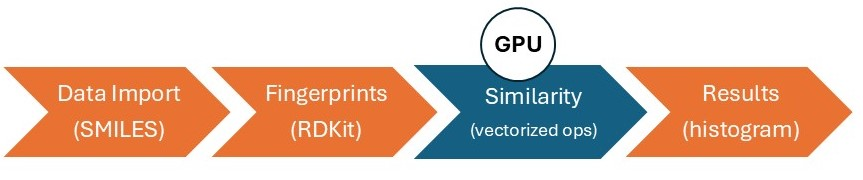

This workflow also exemplifies how MATLAB enables seamless movement of data between GPU and CPU, facilitating high-performance computation alongside easy data management. 

### Requirements

- [Python](https://www.python.org/)

- [RDKit](https://www.rdkit.org/) Open-Source Cheminformatics Software

#### Install Python 

Set up your Python environment by following the instructions provided in the guide found at [Python](https://www.python.org/downloads/release/python-3110/) webpage. Make sure to give the python address and to check versions of Python compatible with MATLAB products by release. This allows to build proper [MATLAB Interface to Python](https://www.mathworks.com/support/requirements/python-compatibility.html). 

% Set path to Python.exe
pythonExecutable = 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311/python.exe'; 

% Set the Python executable in MATLAB
pyenv('Version', pythonExecutable);

% Verify Python configuration
disp('Python version:');

Python version:


pyversion


       version: '3.11'
    executable: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311\python.exe'
       library: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311\python311.dll'
          home: 'C:\Users\hjooya\AppData\Local\Programs\Python\Python311'
      isloaded: 0



warning('off','all')

#### Install RDKit

This example uses some of the functions from RDKit. It can be installed easily by following its [installation](https://www.rdkit.org/docs/Install.html) instructions on Linux, Windows, and macOS. You can install RDKit using pip.

#### Check GPU Availability

if gpuDeviceCount > 0
    gpuInfo = gpuDevice;
    fprintf('GPU detected: %s\n', gpuInfo.Name);
else
    disp('No compatible GPU detected on this machine.');
end


### **Import and Prepare Molecular Data**

The data is read into a table format ([readtable](https://www.mathworks.com/help/matlab/ref/readtable.html)), allowing easy access to its columns. Specifically, we extract the SMILES strings and convert them into a Python list, preparing the data for subsequent processing with RDKit.

% Get the current working directory
currentFolderPath = pwd;

% Define the CSV file name
fileName = 'LogP_LogS.csv';

% Construct the full file path
filePath = fullfile(currentFolderPath, fileName);

% Read the CSV file into a table
data = readtable(filePath);

% Convert the table to a cell array to access SMILES strings
smilesList = data.SMILES'; % Assuming the SMILES column is named 'SMILES'

% Convert SMILES list to Python list
pySmilesList = py.list(smilesList);

### **Generate Molecular Fingerprints**

Molecular fingerprints are digital representations of chemical structures that encode the presence or absence of specific substructures or features within a molecule. 

Molecular fingerprints are widely used in cheminformatics for tasks such as molecular similarity searching, clustering, and virtual screening. 

In this section, we use the RDKit library to generate Morgan fingerprints (also known as circular fingerprints), which are a popular type of molecular fingerprint that captures the local atomic environment around each atom in a molecule. 

Morgan fingerprints are particularly effective for comparing molecular structures and are commonly used in drug discovery and chemical informatics. 

For more information on molecular fingerprints, see the [RDKit documentation](https://www.rdkit.org/docs/GettingStartedInPython.html#fingerprintshttps://www.rdkit.org/docs/GettingStartedInPython.html).

% Calculate fingerprints for each molecule using RDKit (a numpy array).
fingerprints_py = pyrunfile('Compute_Fingerprints.py', 'fingerprints', smilesList=pySmilesList);

% Convert Python numpy array to MATLAB logical matrix
fingerprints = logical(fingerprints_py); % (numMolecules x 2048), each row is a bit vector


### **Move fingerprints to GPU**

In this part of the code, the molecular fingerprint matrix is transferred from the computer’s main memory (CPU) to the graphics processing unit (GPU) by converting it into a `gpuArray` object using the [`gpuArray`](https://www.mathworks.com/help/parallel-computing/gpuarray.html) function. This enables all subsequent operations on the `fingerprints_gpu` variable to be executed directly on the GPU, taking advantage of its parallel processing capabilities for significant speedup. 

% Move fingerprints to GPU
fingerprints_gpu = gpuArray(fingerprints);

numMolecules = size(fingerprints_gpu, 1);

### Compute pairwise Tanimoto similarity matrix on GPU

This section of the code efficiently computes the pairwise Tanimoto similarity matrix directly on the GPU by leveraging vectorized operations on `gpuArray` objects. Instead of using nested loops and repeatedly calling a Python function to compare each pair of molecules (an approach that is computationally expensive and slow for large datasets) this method performs all calculations in parallel using matrix operations. 

First, we compute the bit count (the number of “1” bits) for each molecule’s binary fingerprint. Then, it calculates the intersection matrix, where each element represents the number of shared “1” bits between two molecules, using simple matrix multiplication. The union matrix is similarly constructed using the bit counts and intersection values. Finally, the Tanimoto similarity for every pair is computed as the ratio of the intersection to the union. 

By avoiding explicit loops and offloading the computation to the GPU, this approach dramatically accelerates the calculation of similarity matrices, making it practical to analyze very large chemical datasets in MATLAB. 

% Tanimoto(A,B) = (A & B).sum / (A.sum + B.sum - (A & B).sum)

% Calculate bit counts for each molecule
bitCounts = sum(fingerprints_gpu, 2); % (numMolecules x 1)

% Compute intersection matrix (numMolecules x numMolecules)
intersection = fingerprints_gpu * fingerprints_gpu'; % Each (i,j) is #(on bits in both i and j)

% Compute union matrix
bitCounts_mat = repmat(bitCounts, 1, numMolecules); % (numMolecules x numMolecules)
union = bitCounts_mat + bitCounts_mat' - intersection;

% Tanimoto similarity
similarityMatrix_gpu = intersection ./ union;
similarityMatrix_gpu(union == 0) = NaN; % Handle division by zero

### **Move result back to CPU**

After computing the pairwise similarity matrix on the GPU, the code uses the [`gather`](https://www.mathworks.com/help/matlab/ref/tall.gather.html) function to transfer the `similarityMatrix_gpu` data from GPU memory back to the CPU workspace as a standard MATLAB array. This step is necessary because subsequent operations, such as saving the results or further analysis, typically require the data to be accessible in the main system memory. 

similarityMatrix = gather(similarityMatrix_gpu);

% Save the similarity matrix
save('similarities_from_csv.mat', 'similarityMatrix');

### Visualize Pairwise Similarity Distribution

We can now visualize the distribution of pairwise molecular similarities by plotting a histogram of the calculated similarity values. 

By extracting the upper triangle of the similarity matrix (excluding the diagonal), the code collects all unique pairwise similarity scores between molecules. 

A histogram is then generated to display how these similarity values are distributed across the dataset. 

Using a histogram for this purpose provides an intuitive overview of the molecular diversity within this dataset: in this case, the distribution is skewed towards lower similarity values (mostly below 0.5 and concentrated under 0.25), indicating that the molecules are generally quite diverse and structurally dissimilar from one another. 

This visualization helps us quickly assess the overall similarity landscape of the molecular collection with High LogP and High LogS.

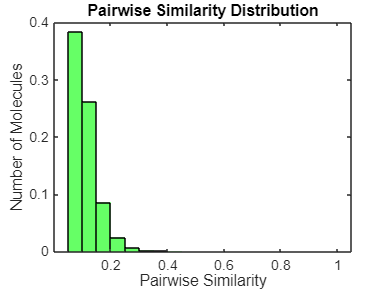

% Extract the upper triangle of the similarity matrix
upperTriangleIndices = find(triu(ones(numMolecules), 1));
similarityValues = similarityMatrix(upperTriangleIndices);

% Define histogram parameters/bins
bins = 0.05:0.05:1.0;
weights = ones(size(similarityValues)) / numel(similarityValues);

% Plot histogram
figure;
histogram(similarityValues, bins, 'Normalization', 'probability', 'FaceColor', 'green', 'EdgeColor', 'black');
title('Pairwise Similarity Distribution');
xlabel('Pairwise Similarity');
ylabel('Number of Molecules');
saveas(gcf, 'similarity_histogram.png');

### Bin Molecules by Pairwise Similarity and Export Results

In this section we group molecules into bins based on their pairwise similarity values. For each unique pair of molecules, the code checks which similarity interval (bin) the pair falls into. Each molecule is then assigned to the appropriate bin if it has not already been assigned. The molecules in each bin are exported to separate CSV files.

Finally, the code verifies that all molecules are accounted for. 

This method provides a simple way to organize molecules by similarity, without performing clustering (which would require a more advanced algorithm to detect natural groupings in the data).

% Call the binning and exporting function
[binnedData, numMoleculesInBins] = binAndExportMolecules(similarityMatrix, bins, data);

% Print the number of molecules in each bin
for i = 1:length(numMoleculesInBins)
    if numMoleculesInBins(i) > 0
        fprintf('Bin %d: %d molecules\n', i, numMoleculesInBins(i));
    end
end

Bin 1: 6600 molecules
Bin 2: 3039 molecules
Bin 3: 218 molecules
Bin 4: 42 molecules
Bin 5: 25 molecules
Bin 6: 13 molecules
Bin 7: 3 molecules
Bin 8: 3 molecules



% Accumulate total number of molecules
totalMoleculesInBins = sum(numMoleculesInBins);
numMolecules = size(similarityMatrix, 1);

% Verify total number of molecules
fprintf('Total molecules in original dataset: %d\n', numMolecules);

Total molecules in original dataset: 9943


fprintf('Total molecules in all bins: %d\n', totalMoleculesInBins);

Total molecules in all bins: 9943



if totalMoleculesInBins == numMolecules
    disp('The total number of molecules in all bins matches the original dataset.');
else
    disp('Warning: The total number of molecules in all bins does not match the original dataset.');
end

The total number of molecules in all bins matches the original dataset.


### Visualize Molecules from a Selected Bin with LogP/LogS Annotations

This section allows you to easily explore the structural and physicochemical characteristics of molecules grouped by similarity, supporting tasks such as lead selection or diversity assessment.

The code visualize molecules grouped within a specific similarity bin. After the bin number is selected, the code reads the corresponding CSV file (e.g., `bin_6.csv`) containing molecular data, including SMILES strings and associated properties such as logP and logS. For each molecule in the selected bin, the code generates a subplot, rendering the molecular structure using the `RDKitDraw` function and annotating it with its logP and logS values. The resulting figure provides a convenient overview of the chemical diversity and property distribution within the chosen bin for further inspection and analysis. 

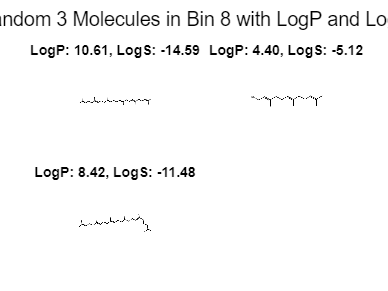

Randomly selected molecules in bin_8.csv have been drawn.


binNumber = 8;         % Select the bin to visualize
numToDraw = 3;        % Number of molecules to draw
try
    drawMoleculesInBin(binNumber, currentFolderPath, pythonExecutable, numToDraw);
    fprintf('Randomly selected molecules in bin_%d.csv have been drawn.\n', binNumber);
catch ME
    disp(ME.message);
end

### Conclusion

This example demonstrates how GPU acceleration in MATLAB can dramatically streamline the analysis of large molecular datasets. By integrating Python-based cheminformatics tools for fingerprint generation and leveraging the GPU for efficient, vectorized computation of pairwise Tanimoto similarities, we efficiently cluster and visualize the chemical diversity within the dataset. The approach scales to thousands of molecules, enabling rapid, high-throughput similarity analysis and data exploration that would be prohibitively slow with traditional CPU-based or loop-based methods. This exemplifies the power and flexibility of combining MATLAB, Python, and GPU computing for modern cheminformatics and big data drug discovery workflows.

### Exercise

Download the “Tox21” dataset from [MoleculeNet](https://moleculenet.org/datasets-1), which contains information about the toxicity of various small molecules. Import this dataset into MATLAB, generate molecular fingerprints, and compute the pairwise similarity matrix using the GPU-enabled workflow from this example.

**(a)** Examine clusters or bins of molecules with high structural similarity. Do you observe recurring functional groups or substructures ([toxicophores](https://www.sciencedirect.com/topics/pharmacology-toxicology-and-pharmaceutical-science/toxicophore#:~:text=Toxicophores%20are%20functional%20groups%2Fsubstructures,marketed%20drugs%2Finvestigational%20drug%20candidates.)) in molecules that are classified as toxic?  

**(b)** Compare these findings to non-toxic clusters: are there structural motifs that appear to be associated with lower toxicity?

### **References**

**[1]** A. A. Kattuparambil, et. al., "Exploring chemical space for “druglike” small molecules in the age of AI", *Front Mol. Biosci. 12, 1553667 (2025)*.

**[2]** Oliver Wieder, et. al., "Improved Lipophilicity and Aqueous Solubility Prediction with Composite Graph Neural Networks", Molecules 2021, 26, 6185. 